# Inverted Cart Pendulum

$\vec{x} = \pmatrix{\bf{q_1} \cr \bf{q_2} \cr \bf{\dot{q_1}} \cr \bf{\dot{q_2}}} $     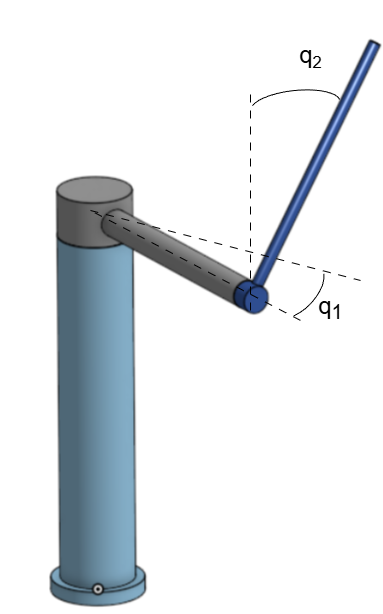

see MATLAB for **Solve Differential Algebraic Equations (DAEs)**

**see **[YouTube](https://www.youtube.com/watch?v=hAI8Ag3bzeE&t=210s)** video**

## Get Linearized System

clearvars;

if(~exist('functions_from_symbolics.mat','file'))
    run Deriving_EOMs.mlx
else
    load functions_from_symbolics.mat
end

## Linear Simulation

iCond = [0.0; deg2rad(120); 0.0; 0.0];
tInit = 0;
tFinal = 10;
tSpan = (tInit:0.01:tFinal)';
u_val = zeros(size(tSpan));

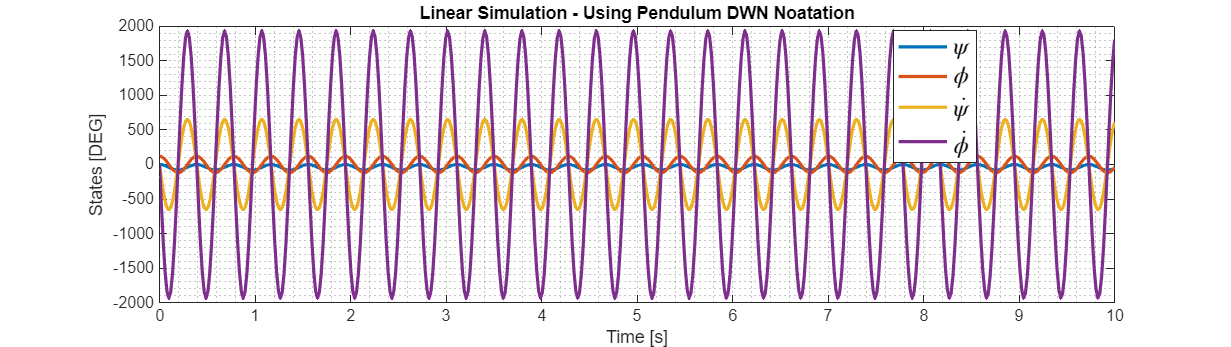

C = eye(size(A_dwn_num));
D = zeros(1, size(B_dwn_num,2));

sys = ss(A_dwn_num, B_dwn_num, C, D); %full state available

[sols, ts] = initial(sys, iCond, tFinal);

figure('Units','normalized', 'Position',[0 0 0.6 0.3])

plot(ts, rad2deg(sols), 'LineWidth',2), hold on

legend({'$\psi$', '$\phi$', '$\dot{\psi}$', '$\dot{\phi}$'}, 'Location',"best",...
    'Interpreter',"latex", "FontSize",15, 'ItemHitFcn',@clickLegendToHide);
title('Linear Simulation - Using Pendulum DWN Noatation')
xlabel('Time [s]');
ylabel('States [DEG]')
grid minor

## Check Observability

O1 = obsv(A_dwn_num, C(1,:));
det(O1) ~= 0

ans = logical
   1


sys1 = ss(A_dwn_num, B_dwn_num, C(1, :), D); %only - head angle is measured
G1 = gram(sys1,'o');

Error using StateSpaceModel/gram (line 62)
Gramians cannot be computed for models with unstable dynamics.